# Plot Spike raster and PSTH

## Simulate spike data

fr = 30; % Hz
dt = 1/1000; % millisecond
nBins = floor(1/dt); % bins
nTrials = 20; % number of simulations/trials
spikeMat = rand(nTrials, nBins) < fr*dt;
tVec = 0:dt:1-dt;

## Spike data

% Each row is a new trial
% Each column corresponds to a time point on the tVec vector

## Plot a single trial

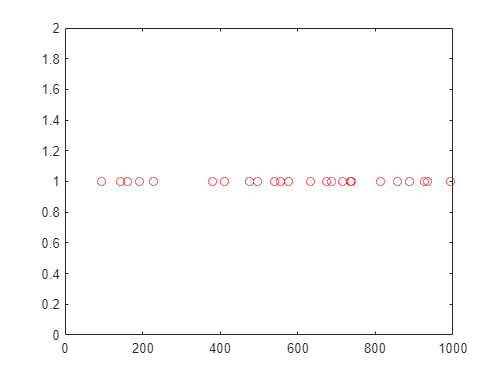

spkLocsT1 = find(spikeMat(1,:));
plot(spkLocsT1,ones(size(spkLocsT1)),'ro')

## Plot a single trial as raster

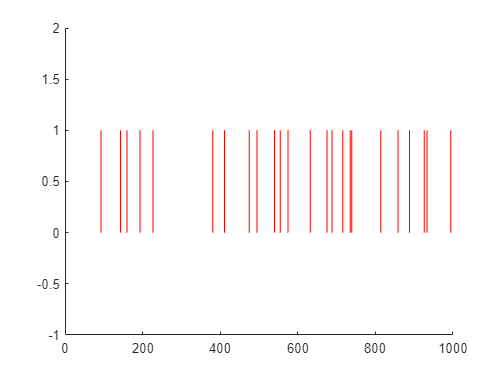

figure;
line([spkLocsT1 ; spkLocsT1] , [zeros(size(spkLocsT1)) ; ones(size(spkLocsT1))], 'Color' , 'r')
ylim([-1 2])

## Plot all trials as raster

% Loop through trial number
figure;
for li = 1:size(spikeMat,1)
    tmpTrial = find(spikeMat(li,:));
    
    % Y values
    % Ybottom
    ybot = zeros(size(tmpTrial)) + li;
    % Ytop
    ytop = ones(size(tmpTrial)) + li;
    
    line([tmpTrial ; tmpTrial] , [ybot ; ytop] , 'Color' ,'k')
    
end

% Xticks 
xAxis = 1:1:size(spikeMat,2)

xAxis =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


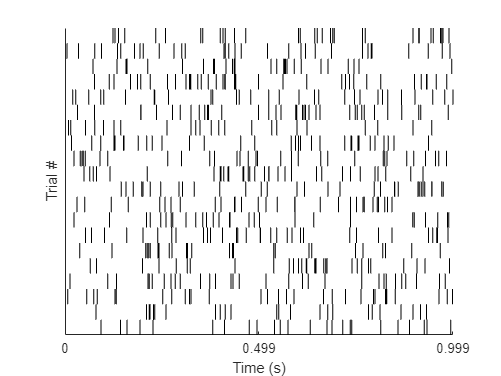

xticks([min(xAxis) round(max(xAxis)/2) max(xAxis)]);
xticklabels(tVec([min(xAxis) round(max(xAxis)/2) max(xAxis)]))
yticks([])

ylabel('Trial #')
xlabel('Time (s)')
ylim([1 21])

## Plot a PSTH - one version

trialSum = sum(spikeMat) % Adds up spike trains across trials

trialSum =      0     0     0     0     1     0     1     0     1     0     0     0     1     0     1     0     1     0     0     1     0     0     2     0     0     0     0     1     0     0     1     1     0     0     1     0     0     1     1     0     0     0     0     1     0     0     1     0     1     0


smoothWidth = 100 % smooth data over bins

smoothWidth = 100

trialSum_smVectM = smoothdata(trialSum ,'movmean', smoothWidth);
trialSum_smVectG = smoothdata(trialSum ,'gaussian', smoothWidth);
psthDM = trialSum_smVectM/(nTrials*dt);
psthDG = trialSum_smVectG/(nTrials*dt);

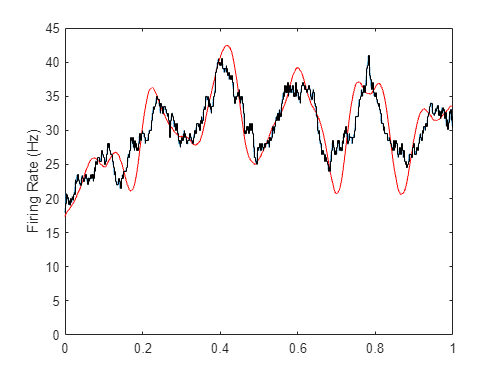


figure(2)
plot(tVec,psthDM)
ylim([0 45])
ylabel('Firing Rate (Hz)')
hold on
plot(tVec,psthDG,'r')
stairs(tVec,psthDM,'k')